clear all

path='C:\Users\maria.pacheco\Documents\GitHub\basicAnalysis'

path = 'C:\Users\maria.pacheco\Documents\GitHub\basicAnalysis'

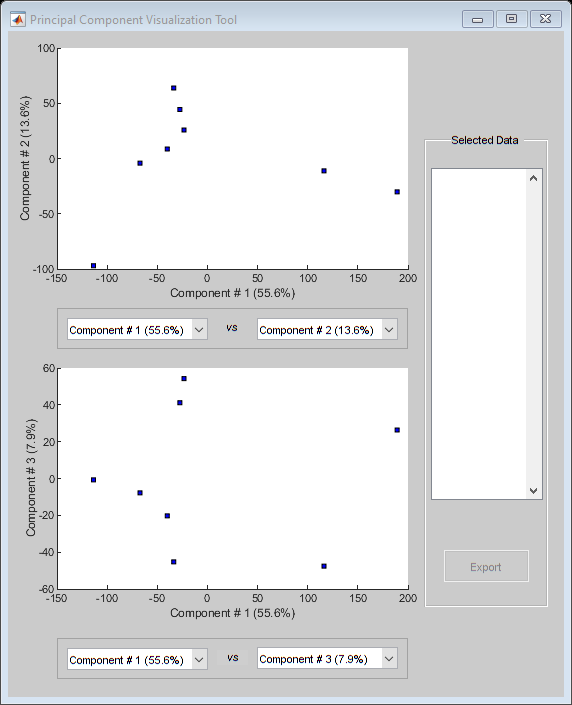

counts = readtable(strcat(path,"\Data\GSE112568_count_table_CRC_C_Williams_Addendum.txt"));
% Length should be download from biomart pay attention to the right assembly 
%https://www.ensembl.org/biomart/martview/86ee26709c0735e01f47aad88718ba5e
lengths = readtable(strcat(path,"\Data\lengths.txt"));
lengths=lengths(:,2:3);

Ensembl= counts.ENSEMBL_ID;
data = log2(table2array(counts(:,3:end))+1);

addpath(genpath(pwd));
cond={'EV', 'EV', 'EV10nME224HR_I',  'EV10nME224HR_I','1uG124hr_I', '1uG124hr_I', 'ERBtransduced','ERBtransduced'};

mapcaplot(data',cond);

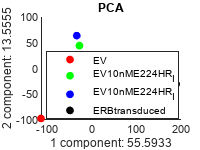

[~,score,~,~,explained,~] = pca(data');
figure
hold on
plot(score(1:2,1),score(1:2,2),'r.', 'MarkerSize',20 )
plot(score(3:4,1),score(3:4,2),'g.', 'MarkerSize',20)
plot(score(5:6,1),score(5:6,2),'b.' ,'MarkerSize',20)
plot(score(7:8,1),score(7:8,2),'k.', 'MarkerSize',20)

title('PCA')
xlabel([num2str(1), ' component: ', num2str(explained(1))])
ylabel([num2str(2), ' component: ', num2str(explained(2))])
legend({'EV','EV10nME224HR_I','EV10nME224HR_I', 'ERBtransduced' },'location','best')

boxplot

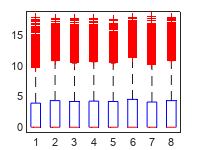

figure
boxplot(data)

[I,IA,IB]=intersect(counts.ENSEMBL_ID,table2array(lengths(:,1)));
data=(data(IA,:));
lengths=table2array(lengths(IB,2));

TPM

temp=data./repmat(lengths,1,size(data,2));
TPM=1000000*temp./repmat(nansum(temp),size(data,1),1);

The sum of TPM for each sample should be 1e6

sum(TPM,1)

ans = 1.0e+06 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


FPKM

temp=1000000*data./repmat(nansum(data),size(data,1),1);
FPKM=temp./repmat(lengths,1,size(data,2));

Densityplot

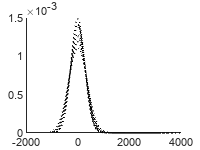

figure
hold on
for i=1:size(TPM,2)    
[probability_estimate,xi] = ksdensity(TPM(:,i));
plot(xi,probability_estimate,':k','LineWidth',1);
end
hold off

FPKM=table(table2array(counts(IA,1:2)),FPKM)

FPKM = 54412×2 table
                   Var1                       FPKM   
    ___________________________________    __________

    {'ENSG00000000003'}    {'TSPAN6'  }    1×8 double
    {'ENSG00000000005'}    {'TNMD'    }    1×8 double
    {'ENSG00000000419'}    {'DPM1'    }    1×8 double
    {'ENSG00000000457'}    {'SCYL3'   }    1×8 double
    {'ENSG00000000460'}    {'C1orf112'}    1×8 double
    {'ENSG00000000938'}    {'FGR'     }    1×8 double
    {'ENSG00000000971'}    {'CFH'     }    1×8 double
    {'ENSG00000001036'}    {'FUCA2'   }    1×8 double
    {'ENSG00000001084'}    {'GCLC'    }    1×8 double
    {'ENSG00000001167'}    {'NFYA'    }    1×8 double
    {'ENSG00000001460'}    {'STPG1'   }    1×8 double
    {'ENSG00000001461'}    {'NIPAL3'  }    1×8 double
    {'ENSG00000001497'}    {'LAS1L'   }    1×8 double
    {'ENSG00000001561'}    {'ENPP4'   }    1×8 double
    {'ENSG00000001617'}    {'SEMA3F'  }    1×8


writetable(FPKM, strcat(path,'\Data\FPKM.txt'))